## Question D

clc
clear
R = 1;
KE = 1e-1;
KT = 1e-1;
J1 = 1e-5;
J2 = 4e-5;
Bf = 2e-3;
D1 = 20;
D2 = 2;

A = [0 0 0 1 0;
     0 0 0 0 1;
     0 (D2/Bf) -(D2/Bf) 0 0;
     -(D1/J1) (D1/J1) 0 -(KT*KE/J1/R) 0;
     (D1/J2) -((D1+D2)/J2) (D2/J2) 0 0];

eigenvalue = eig(A)

eigenvalue = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.0000 + 0.0000i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i



B = [0 0;
     0 0;
     0 1/Bf;
     KT/J1/R 0;
     0 0];

#### case (1)

C_1 = [0 1 0 0 0;
       0 0 0 0 1];
D_1 = [0 0;
       0 0];

sys_1 = ss(A,B,C_1,D_1);
tf_1 = tf(sys_1)

tf_1 =
 
  From input 1 to output...
                              5e09 s + 5e12
   1:  ------------------------------------------------------------
       s^5 + 2000 s^4 + 3.55e06 s^3 + 3.05e09 s^2 + 6e11 s - 0.2545
 
                            5e09 s^2 + 5e12 s
   2:  ------------------------------------------------------------
       s^5 + 2000 s^4 + 3.55e06 s^3 + 3.05e09 s^2 + 6e11 s - 0.2545
 
  From input 2 to output...
                       2.5e07 s^2 + 2.5e10 s + 5e13
   1:  ------------------------------------------------------------
       s^5 + 2000 s^4 + 3.55e06 s^3 + 3.05e09 s^2 + 6e11 s - 0.2545
 
                     2.5e07 s^3 + 2.5e10 s^2 + 5e13 s
   2:  ------------------------------------------------------------
       s^5 + 2000 s^4 + 3.55e06 s^3 + 3.05e09 s^2 + 6e11 s - 0.2545
 
Continuous-time transfer function.



u5=tzero(sys_1)


u5 =

  0×1 empty double column vector



u6=pole(sys_1)

u6 = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.0000 + 0.0000i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i


#### case(2)

C_2 = [0 0 0 -KE/R 0;
       0 D2/Bf -D2/Bf 0 0];
D_2 = [1/R 0;
       0 1/Bf];

sys_2 = ss(A,B,C_2,D_2);
u1=tzero(sys_2)

u1 = 1.0e+03 *

   0.0000 + 0.0000i
  -0.0000 + 1.5843i
  -0.0000 - 1.5843i
  -0.0000 + 0.1996i
  -0.0000 - 0.1996i


u2=pole(sys_2)

u2 = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.0000 + 0.0000i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i



%tf_2 = tf(sys_2)
%[z0,p0,k0] = tf2zp(tf_2.Numerator{1,1},tf_2.Denominator{1,1})

## Question E

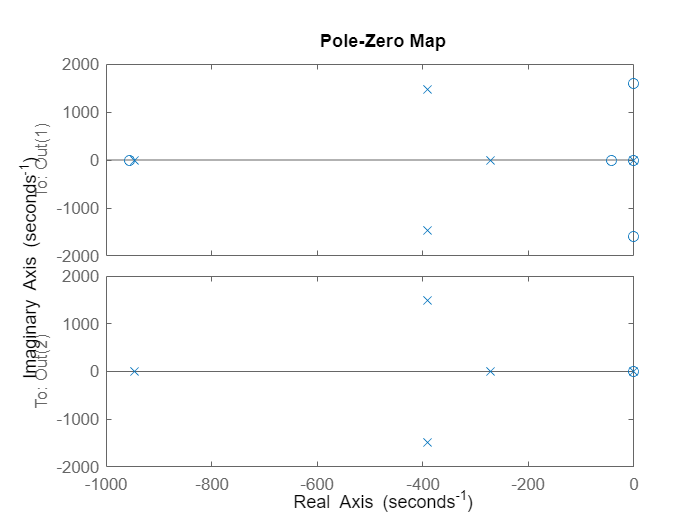

B_3 = [0;
       0;
       0;
       KT/J1/R;
       0];
C_3 = [0 0 0 -KE/R 0;
       0 D2/Bf -D2/Bf 0 0];
D_3 = [1/R;
       0];
sys_3 = ss(A,B_3,C_3,D_3);
iopzplot(sys_3)

% tf_3 = tf(sys_3)
% Tred = minreal(tf_3, 1e-7)
% pzplot(Tred)
% pzplot(tf_3)
%[z,p]=zpkdata(sys_3)
% u3=tzero(sys_3)
% u4=pole(sys_3)
% num_3 = tf_3.Numerator;
% den_3 = tf_3.Denominator;
% Tred = minreal(tf_3, 1e-7)
% pzmap(Tred)
% num_3 = Tred.Numerator;
% den_3 = Tred.Denominator;
% [z1,p1,k1] = tf2zp(num_3{1,1},den_3{1,1})
% [z2,p2,k2] = tf2zp(num_3{2,1},den_3{2,1})
%    % Plot the poles and zeros to verify that they are in the expected locations.
% fvtool(num_3{1,1},den_3{1,1},'polezero');
% fvtool(num_3{2,1},den_3{2,1},'polezero');

## Question F

t = linspace(0,0.2);
u = [10*ones(size(t));
      0*ones(1,length(t)/2) +0.1*ones(1,length(t)/2)];
[y1,t1] = lsim(sys_1,u,t);
[y2,t2] = lsim(sys_2,u,t);

% figure
% subplot(6,1,1)
% plot(t1,u(1,:)); grid on;
% ylabel('v_a')
% subplot(6,1,2)
% plot(t1,u(2,:)); grid on;
% ylabel('T_e')
% subplot(6,1,3)
% plot(t1,y1(:,1)); grid on;
% ylabel('\phi_2')
% subplot(6,1,4)
% plot(t1,y1(:,2)); grid on;
% ylabel('\omega_2')
% subplot(6,1,5)
% plot(t2,y2(:,1)); grid on;
% ylabel('i_a')
% subplot(6,1,6)
% plot(t1,y1(:,2)); grid on;
% ylabel('\omega_3')
% hold on

